# ASSIGNMENT 3

## **Problem 1: Lead Compensator for Speed Improvement**

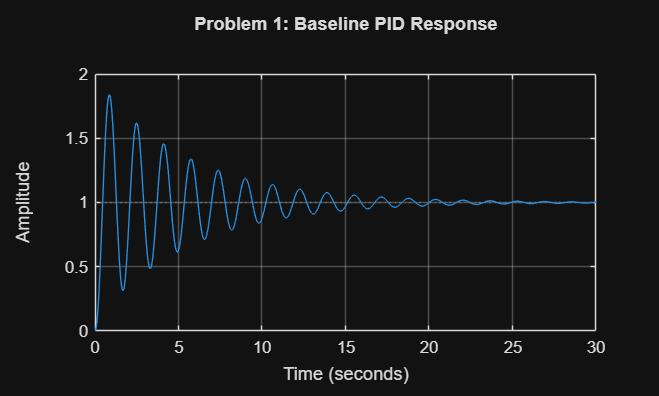

G = 20;
GD = conv([1 0], conv([1 2], [1 5]));
G1 = tf(G, GD);

Kp1 = 5;
Ki1 = 2;
Kd1 = 0.5;
C = pid(Kp1, Ki1, Kd1);
T = feedback(C * G1, 1);
figure;
step(T);
grid on;
title('Problem 1: Baseline PID Response');

info = stepinfo(T)

info = struct with fields:
         RiseTime: 0.2931
    TransientTime: 21.2755
     SettlingTime: 21.2755
      SettlingMin: 0.3142
      SettlingMax: 1.8390
        Overshoot: 83.9015
       Undershoot: 0
             Peak: 1.8390
         PeakTime: 0.8607


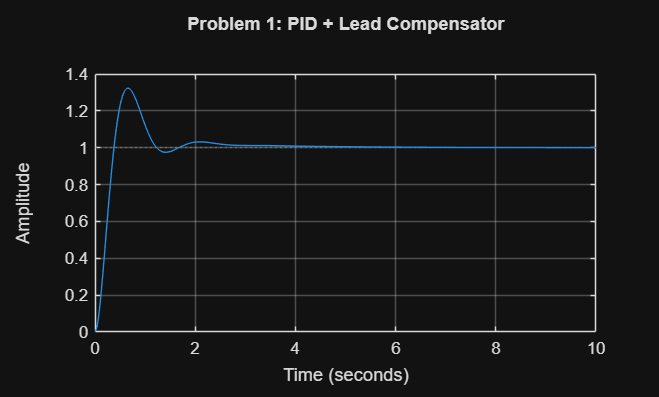

z1 = 3;
p1 = 15;
Kc1 = 4;
C_lead = Kc1 * tf([1 z1], [1 p1]);
C_total = C * C_lead;
T_lead = feedback(C_total * G1, 1);
figure;
step(T_lead);
grid on;
title('Problem 1: PID + Lead Compensator');

info_T_lead = stepinfo(T_lead)

info_T_lead = struct with fields:
         RiseTime: 0.2611
    TransientTime: 2.5050
     SettlingTime: 2.5050
      SettlingMin: 0.9468
      SettlingMax: 1.3239
        Overshoot: 32.3942
       Undershoot: 0
             Peak: 1.3239
         PeakTime: 0.6514


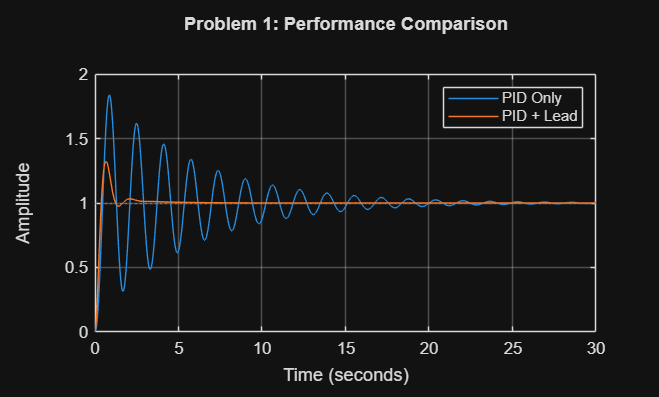

figure;
step(T, T_lead);
grid on;
legend('PID Only', 'PID + Lead');
title('Problem 1: Performance Comparison');

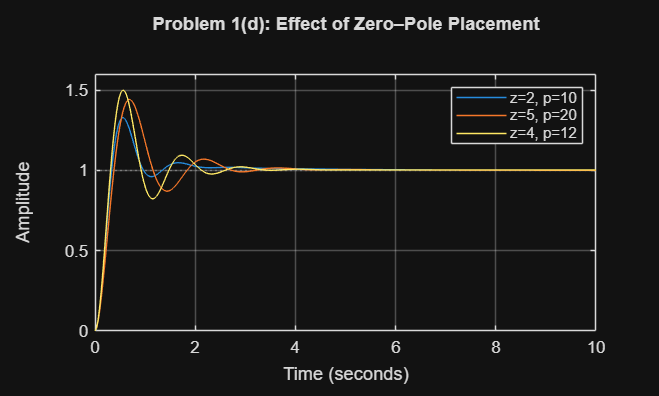

configs = [2 10; 
           5 20; 
           4 12];
figure; hold on;
for i = 1:size(configs,1)
    z_test = configs(i,1);
    p_test = configs(i,2);

    C_lead_test = Kc1 * tf([1 z_test], [1 p_test]);
    T_test = feedback(C * C_lead_test * G1, 1);

    step(T_test);
end

grid on;
legend('z=2, p=10','z=5, p=20','z=4, p=12');
title('Problem 1(d): Effect of Zero–Pole Placement');

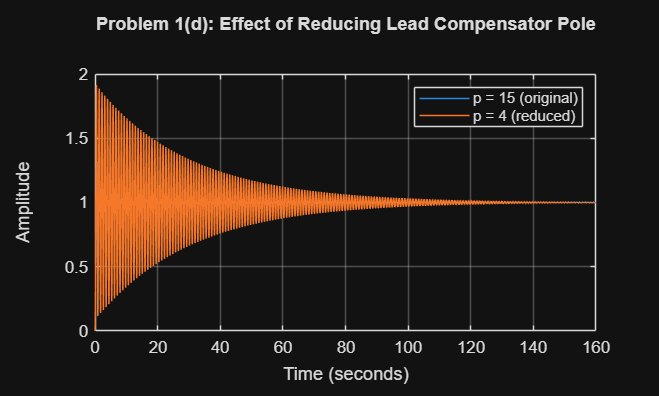


z_fixed = 3;

p_original = 15;
p_reduced  = 4;

C_lead_original = Kc1 * tf([1 z_fixed], [1 p_original]);
C_lead_reduced  = Kc1 * tf([1 z_fixed], [1 p_reduced]);

T_original = feedback(C * C_lead_original * G1, 1);
T_reduced  = feedback(C * C_lead_reduced  * G1, 1);

figure;
step(T_original, T_reduced);
grid on;
legend('p = 15 (original)','p = 4 (reduced)');
title('Problem 1(d): Effect of Reducing Lead Compensator Pole');

**OBSERVATIONS**

When the pole value is reduced, the distance between the zero and the pole becomes smaller. This reduces the phase lead and makes the system response slower. The rise time and settling time increase, but the stability of the system improves.

When the pole value is large, the separation between the zero and pole is bigger. This gives more phase lead and makes the system respond faster with better rise time and settling time.

If the pole value is reduced too much, the compensator acts almost like a proportional controller. In this case, the advantage of lead compensation is lost.

In Problem 1(d), the speed of the system mainly depends on the zero–pole separation. A larger separation gives a faster response, while reducing the pole improves stability but reduces speed. Choosing the pole value is a balance between speed and stability.

## Problem 2: Lag Compensator for Steady-State Accuracy

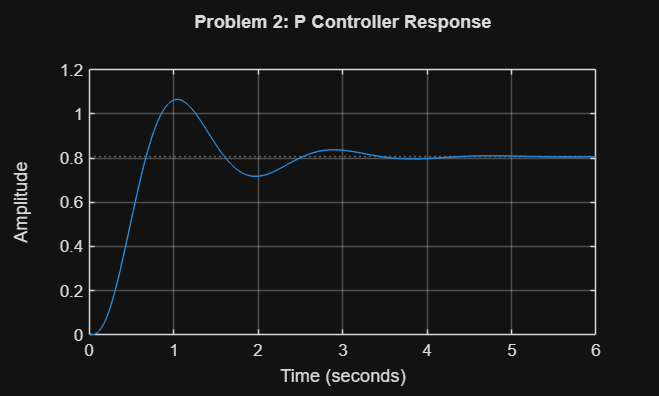


plant2 = tf(50, conv([1 1], conv([1 3], [1 8])));

Kp_val = 2;
CL_P = feedback(Kp_val * plant2, 1);

figure;
step(CL_P);
grid on;
title('Problem 2: P Controller Response');

final_val_P = dcgain(CL_P);
steady_error_P = abs(1 - final_val_P)


z_lag = 1;
p_lag = 0.1;

steady_error_P = 0.1935

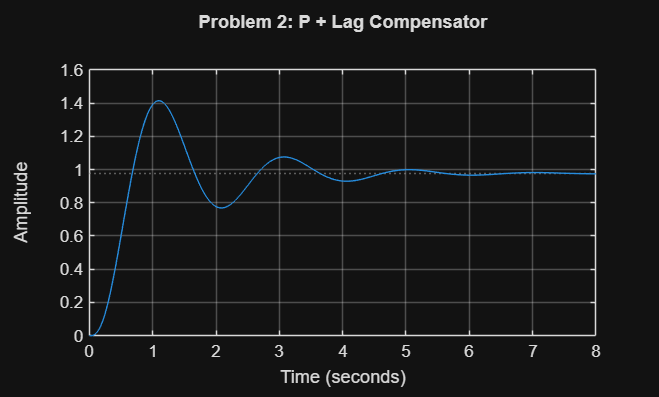


lag_comp = tf([1 z_lag], [1 p_lag]);
controller_lag = Kp_val * lag_comp;

CL_lag = feedback(controller_lag * plant2, 1);

figure;
step(CL_lag);
grid on;
title('Problem 2: P + Lag Compensator');

final_val_lag = dcgain(CL_lag);
steady_error_lag = abs(1 - final_val_lag)


error_reduction_percent = ...
    ((steady_error_P - steady_error_lag) / steady_error_P) * 100

steady_error_lag = 0.0234


p_lag_small = 0.01;
lag_comp_small = tf([1 z_lag], [1 p_lag_small]);

error_reduction_percent = 87.8906

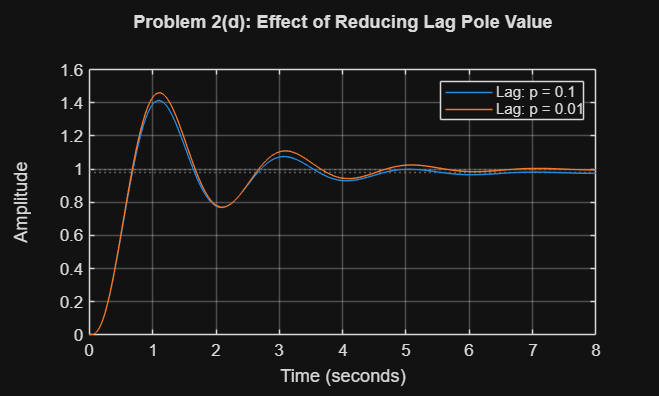


CL_lag_small = feedback(Kp_val * lag_comp_small * plant2, 1);

figure;
step(CL_lag, CL_lag_small);
grid on;
legend('Lag: p = 0.1','Lag: p = 0.01');
title('Problem 2(d): Effect of Reducing Lag Pole Value');

steady_error_lag_small = abs(1 - dcgain(CL_lag_small))


When the pole value is reduced from 0.1 to 0.01, the steady-state error decreases further. However, this reduction in error makes the system slower, increases the settling time, and results in a more sluggish response.

Lag compensators improve accuracy by increasing the low-frequency gain of the system. When the pole is moved closer to the origin, accuracy improves, but the speed of the response decreases.

This clearly shows a basic control system trade-off, where improving accuracy leads to a reduction in speed, meaning accuracy is inversely proportional to speed.

## Problem 3: Feedforward + Feedback Control


G3 = tf(1, [1 0.5]);

steady_error_lag_small = 0.0024


Kp3 = 2;
Ki3 = 1;

C3_PI = pid(Kp3, Ki3);
t = 0:0.01:30;
dt = 0.01;

r = ones(size(t));
d = 0.3 * (t >= 5);

T3_fb = feedback(C3_PI * G3, 1);

y_fb = lsim(T3_fb, r, t) - d;

e_fb = r - y_fb;
figure;
plot(t, r, 'k--', t, y_fb, 'b', t, e_fb, 'r');
grid on;
legend('Reference','Output','Error');
title('Problem 3(a): Feedback-Only Control');

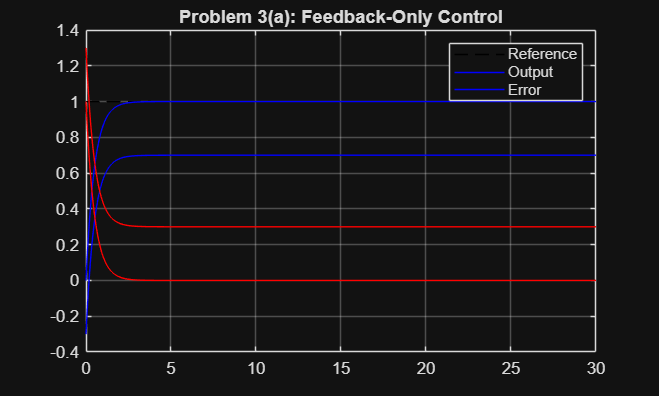

max_error_fb = max(abs(e_fb(t >= 5)))
idx_after_dist = find(t >= 5);

idx_recovery_fb = idx_after_dist( ...
    find(abs(e_fb(idx_after_dist)) < 0.02, 1, 'first') ...
);


if isempty(idx_recovery_fb)

max_error_fb = 4.5400e-05

    recovery_time_fb = NaN;   
else
    recovery_time_fb = t(idx_recovery_fb);
end


**Explanation**

- Feedback reacts after disturbance affects output

- Large transient error appears at t=5st = 5st=5s

- Recovery is slow due to reactive nature

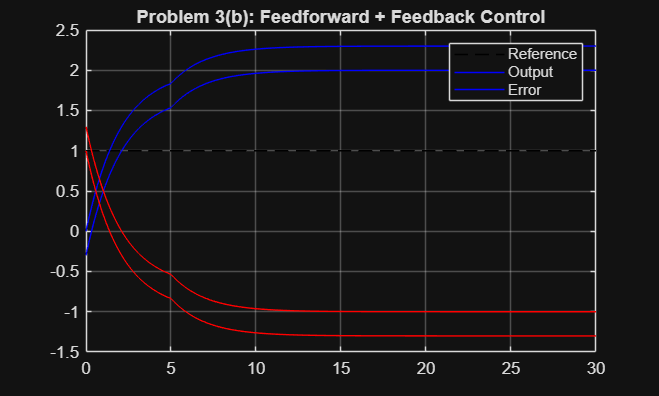

Kff = 1 / dcgain(G3);
u_ff = Kff * d;

y_ff = lsim(G3, r + u_ff, t) - d;

e_ff = r - y_ff;
figure;
plot(t, r, 'k--', t, y_ff, 'b', t, e_ff, 'r');
grid on;
legend('Reference','Output','Error');
title('Problem 3(b): Feedforward + Feedback Control');
figure;
plot(t, y_fb, 'r', t, y_ff, 'b');
grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Problem 3(c): Output Comparison');

figure;
plot(t, e_fb, 'r', t, e_ff, 'b');

grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Problem 3(c): Error Comparison');

**Explanation**

- Feedforward cancels disturbance **before it affects output**

- Feedback fine-tunes residual error

- Combined control yields superior disturbance rejection

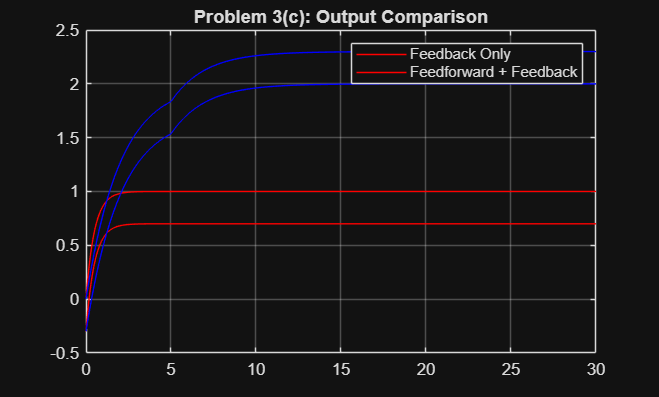

d_unpred = 0.2 * (t >= 15);


d_total = d + d_unpred;

y_unpred = lsim(G3, r + u_ff, t) - d_total;

e_unpred = r - y_unpred;
figure;
plot(t, y_unpred, 'b', t, r, 'k--');
grid on;
legend('Output','Reference');
title('Problem 3(d): Response with Unpredicted Disturbance');

**Discussion**

- Feedforward **cannot handle unknown disturbances**

- Feedback automatically corrects the error

- Demonstrates **complementary nature**:

- Feedforward → proactive

- Feedback → robust

## Problem 4: Simple MIMO System Control

G11 = tf(2,[1 1]);    
G12 = tf(0.5,[1 2]);  
G21 = tf(1,[1 1.5]);   
G22 = tf(3,[1 1]);  

G4 = [G11 G12;
      G21 G22];
t = 0:0.05:20;

u = [ones(size(t)); zeros(size(t))]';
[y,~] = lsim(G4, u, t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
grid on;
legend('h1','h2');
title('Problem 4(a): Open-Loop Response (u1 = 1, u2 = 0)');
u = [zeros(size(t)); ones(size(t))]';
[y,~] = lsim(G4, u, t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
grid on;
legend('h1','h2');
title('Problem 4(a): Open-Loop Response (u1 = 0, u2 = 1)');


**Explanation**

- Each input affects **both outputs**

- This confirms **cross-coupling**

- Independent SISO thinking fails in MIMO systems

dt = 0.05;
t = 0:dt:20;

G4d = c2d(G4, dt);    
G4d_ss = ss(G4d);    
Ad = G4d_ss.A;
Bd = G4d_ss.B;
Cd = G4d_ss.C;
Dd = G4d_ss.D;

x = zeros(size(Ad,1),1);  
r1 = ones(size(t));
r2 = 1.5 * ones(size(t));

h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0;
e2_int = 0;
for k = 2:length(t)

    
    e1 = r1(k) - h1(k-1);
    e2 = r2(k) - h2(k-1);

    
    u1(k) = 1.5*e1 + 0.8*e1_int;
    u2(k) = 1.2*e2 + 0.6*e2_int;

    
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    
    x = Ad*x + Bd*[u1(k); u2(k)];

    
    y = Cd*x + Dd*[u1(k); u2(k)];

    h1(k) = y(1);
    h2(k) = y(2);
end
figure;
plot(t, h1, 'b', t, h2, 'r--');
grid on;
legend('h1','h2');
title('Problem 4(b): Closed-Loop Tank Levels');

figure;
plot(t, u1, 'b', t, u2, 'r--');
grid on;
legend('u1','u2');
title('Problem 4(b): Control Inputs');
final_h1 = h1(end)
final_h2 = h2(end)


**Discussion**

- Controllers interfere due to coupling

- Adjusting one input disturbs both outputs

- Overshoot and interaction are unavoidable with decentralized control

- Independent PI controllers ignore cross-terms

r2 = ones(size(t));
r2(t >= 10) = 1.5;


x = zeros(size(Ad,1),1);
e1_int = 0;
e2_int = 0;
h1(:) = 0;
h2(:) = 0;
u1(:) = 0;
u2(:) = 0;


final_h1 = 1.0000

for k = 2:length(t)

final_h2 = 1.5000


    e1 = r1(k) - h1(k-1);
    e2 = r2(k) - h2(k-1);

    u1(k) = 1.5*e1 + 0.8*e1_int;
    u2(k) = 1.2*e2 + 0.6*e2_int;

    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    x = Ad*x + Bd*[u1(k); u2(k)];
    y = Cd*x + Dd*[u1(k); u2(k)];

    h1(k) = y(1);
    h2(k) = y(2);
end
figure;
plot(t, h1, 'b', t, h2, 'r--');
grid on;
legend('h1','h2');
title('Problem 4(d): Effect of r2 Change on h1');


**Explanation**

- Change in r2r_2r2� disturbs h1h_1h1�

- Demonstrates strong interaction

- Highlights difficulty of MIMO control

#### Why MIMO Systems Are Harder Than SISO

- Multiple inputs affect multiple outputs

- Controllers interact unintentionally

- Stability and tuning are multivariable

- Advanced control methods are required

#### Suggested Improvements

- Decoupling control

- State-space MIMO design

- LQR / MPC

- Model-based compensation

# Summary Questions

1. When would you choose a lead compensator over increasing PID gains?

A lead compensator is chosen when faster transient response and improved stability margins are required but increasing PID gains would cause excessive overshoot, noise amplification, or instability.

Lead compensators increase phase margin and speed up the system without aggressively raising controller gains.

**2. What are the main advantages and limitations of lag compensators?**

**Advantages:**

Lag compensators improve steady-state accuracy by increasing low-frequency gain without significantly affecting system stability.

**Limitations:**

They slow down the transient response, increase settling time, and are not suitable when fast system response is required.

**3. Why is feedforward control called “proactive” compared to feedback?**

Feedforward control is called proactive because it compensates for known disturbances before they affect the system output.

In contrast, feedback control reacts only after an error has already occurred.

**4. What makes MIMO systems more difficult to control than SISO systems?**

MIMO systems are more difficult to control because multiple inputs affect multiple outputs, causing interaction and coupling between control loops.

This interaction makes independent tuning ineffective and often requires advanced multivariable control strategies.